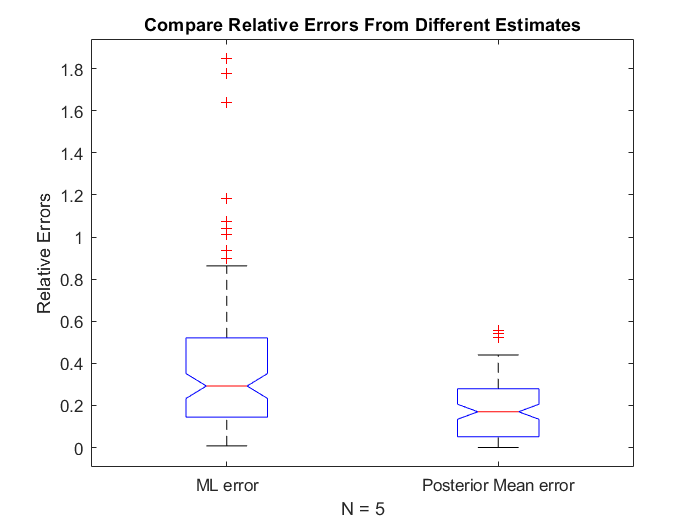

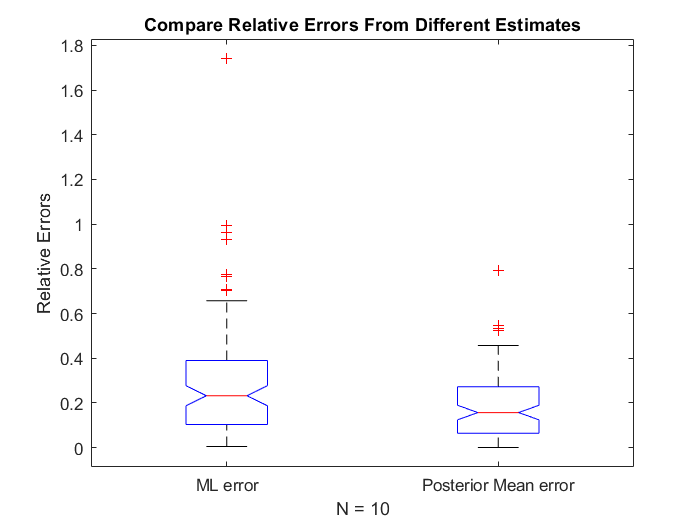

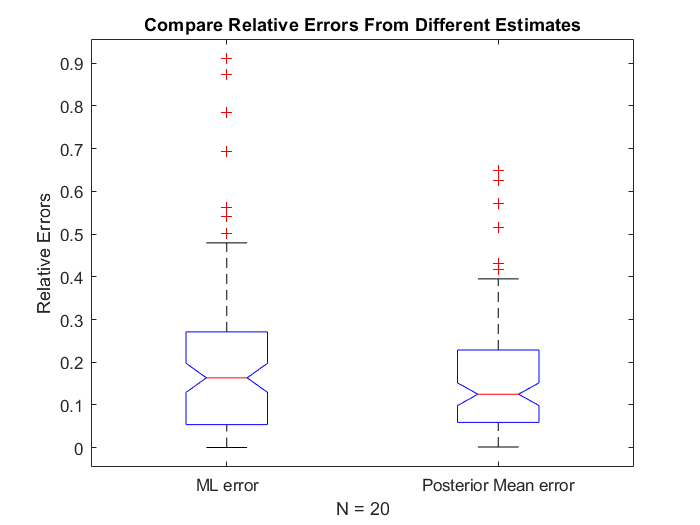

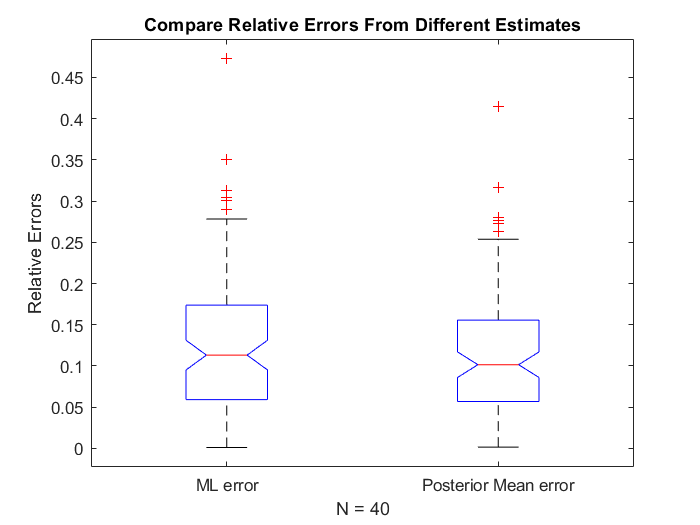

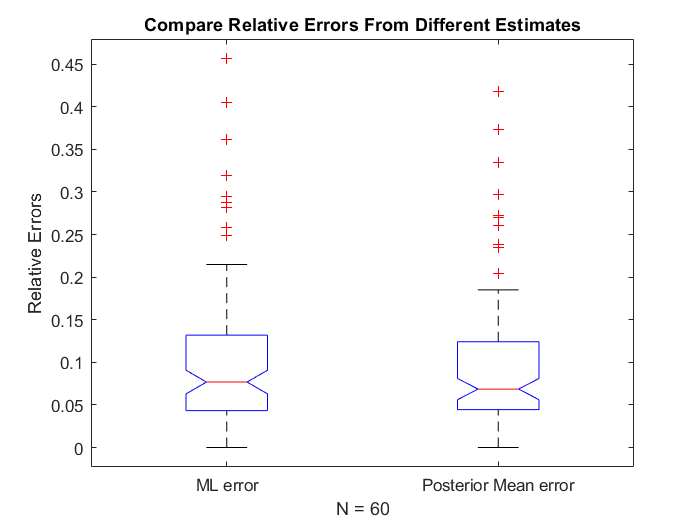

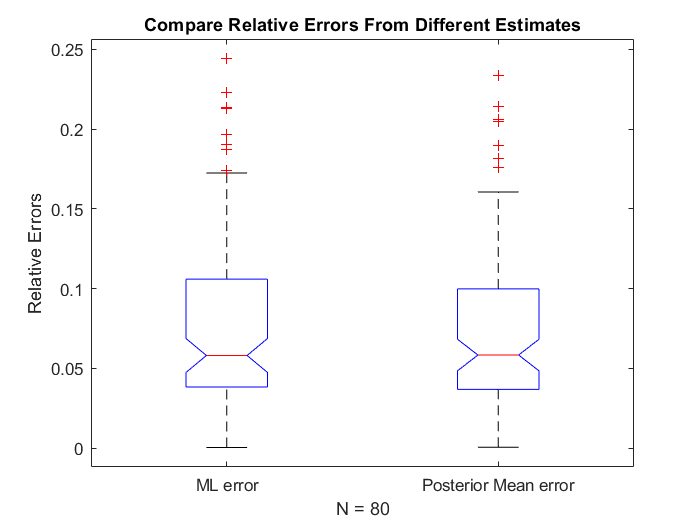

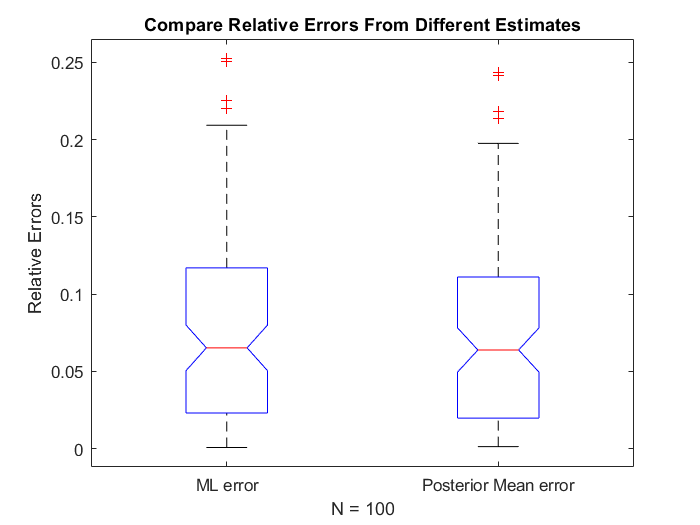

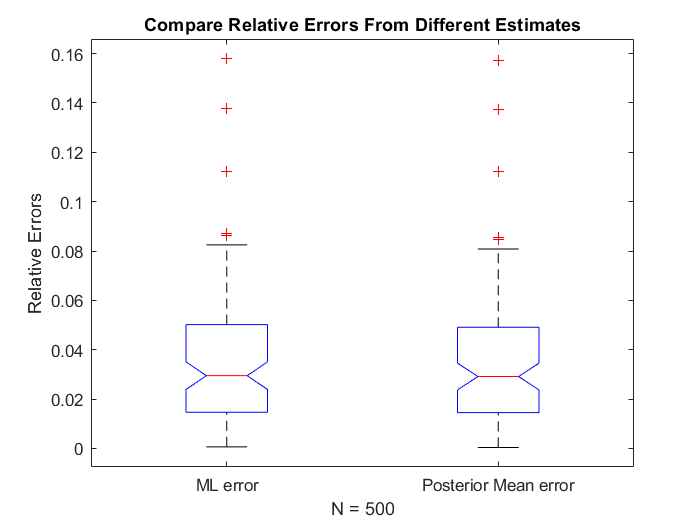

rng("default")

N = [5, 10, 20, 40, 60, 80, 100, 500, 1000 10000]; % Sizes of the different datasets
m = 100; % Number of times an experiment is repeated
errors_ML = zeros(m,10);
errors_posterior = zeros(m,10);
for j = 1:10
    n = N(j); % The size of dataset being used
    lambda = 5; % The given true lambda
    error_ML = zeros(m,1); % Stores error values of ML estimate
    error_posterior = zeros(m,1); % Stores error values of Posterior Mean estimate
    for i = 1:m
        uniform_data = rand(1,n); % Generating the random data from the uniform distribution
        transformed_data = -1*log(uniform_data)/lambda; % Transforming the data according to the given equation 
        
        % We find out that the PDF of the transformed variable is that of an exponential distribution

        % Finding the sample mean
        sample_mean = sum(transformed_data)/n;

        % Finding the ML estimate which is equal to reciprocal of sample mean for exponential distribution
        lambda_ML = 1/sample_mean;
        
        % The Prior is a gamma function with parameters:
        alpha = 5.5;
        beta = 1;
        
        % The Prior of a gamma function is a conjugate prior for exponential distribution 
        
        % So applying the concept of cojugate priors, we get the posterior
        % distribution as a gamma function with the following new parameters:
        alpha_posterior = alpha + n;
        beta_posterior = beta + sum(transformed_data);
    
        % We know that the mean of a gamma function is alpha/beta, so:

        % Finding the Posterior Mean
        lambda_posterior_mean = alpha_posterior/beta_posterior;

        % Calculating and storing the relative values of the errors
        error_ML(i,1) = abs(lambda_ML - lambda)/lambda;
        error_posterior(i,1) = abs(lambda_posterior_mean-lambda)/lambda;
    end
    % Making the boxplots of the errors for different values of the dataset size
    figure
    boxplot([error_ML,error_posterior],'Notch','on','Labels',{'ML error','Posterior Mean error'},'Whisker',1)
    title(sprintf('Compare Relative Errors From Different Estimates'))
    xlabel(sprintf('N = %d',n))
    ylabel('Relative Errors')
    errors_ML(:,j) = error_ML;
    errors_posterior(:,j) = error_posterior;
end

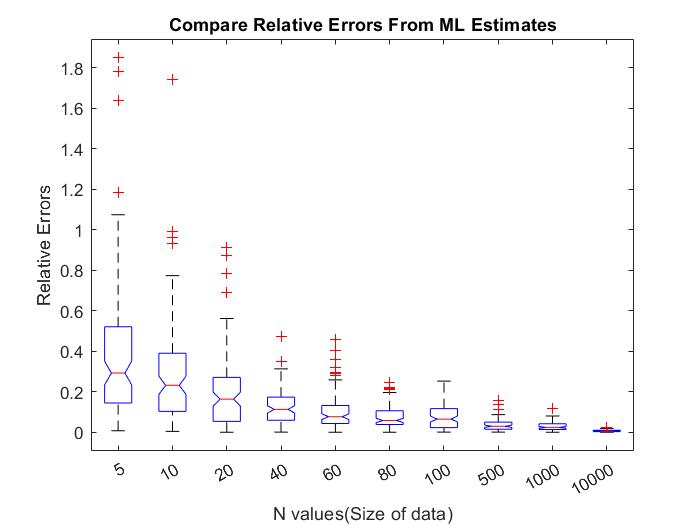

% Plotting only the ML errors for different values of N
figure 
boxplot(errors_ML,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From ML Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

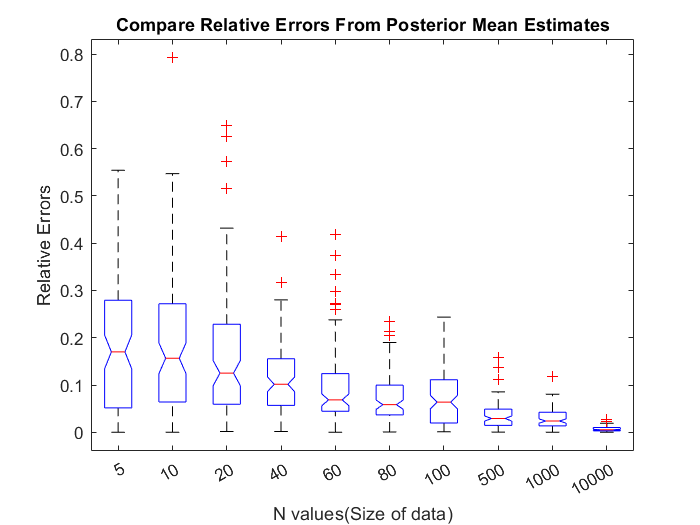

% Plotting only the Posterior Mean errors for different values of N
figure 
boxplot(errors_posterior,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From Posterior Mean Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

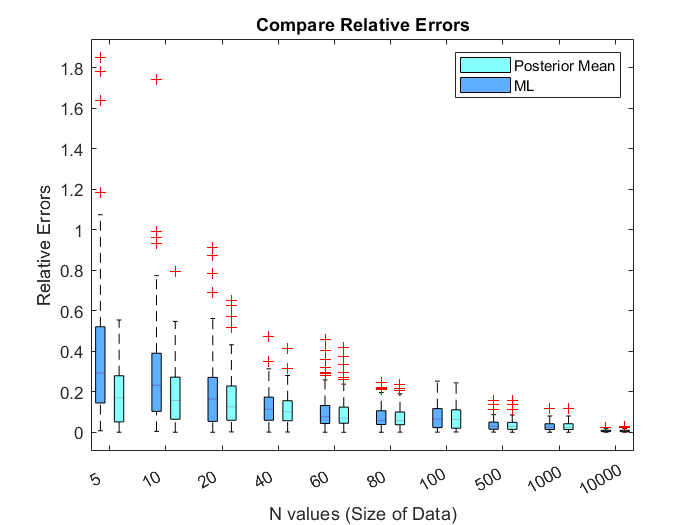

% Plotting both the errors together for different values of N
figure
data=cell(10,3);
for ii=1:size(data,1)
Ac{ii}=errors_ML(:,ii);
Bc{ii}=errors_posterior(:,ii);
end
data=vertcat(Ac,Bc);
xlab=N;
col=[102,255,255, 200;
51,153,255, 200];
col=col/255;
multiple_boxplot(data',xlab,{'ML', 'Posterior Mean'},col')
xlabel('N values (Size of Data)');
ylabel('Relative Errors');
title('Compare Relative Errors')